%% Hw3-Part2.2 %%%goodnew
clc; clear; close all;

%% 参数设置
N = 400;            % 总数据点数
T0 = 200;           % 真实突变点
MC = 4000;          % Monte Carlo 实验次数
rho = 0.8;          % AR(1) 过程的系数
phi = pi/4;         % AR(2) 过程的相位
sigma_alpha = 1;    % AR(1) 噪声标准差
sigma_beta = 1;     % AR(2) 噪声标准差

a1 = 0.5;           % AR(2) 过程的系数
a2 = -0.3;          % AR(2) 过程的系数

%% Monte Carlo 仿真
mse_values = zeros(MC, 1); % 存储 MSE 结果
posterior_prob_all = zeros(MC, N); % 存储每次实验的后验概率分布
estimated_T_hat = zeros(MC, 1); % 存储每次实验的估计 T_hat
AR1_coeff_all = zeros(MC, 1); % 存储每次实验的 AR(1) 估计参数
AR2_coeff_all = zeros(MC, 2); % 存储每次实验的 AR(2) 估计参数

for mc = 1:MC
    % 生成 AR(1) 过程 (n ≤ T0)
    x = zeros(N, 1);
    x(1) = sqrt(sigma_alpha) * randn; % 初始值
    for n = 2:T0
        x(n) = rho * x(n-1) + sqrt(sigma_alpha) * randn;
    end
    
    % 生成 AR(2) 过程 (n > T0)
    x(T0+1) = sqrt(sigma_beta) * randn;
    x(T0+2) = sqrt(sigma_beta) * randn;
    for n = T0+3:N
        x(n) = a1 * x(n-1) + a2 * x(n-2) + sqrt(sigma_beta) * randn;
    end
    
    %% AR 参数估计（通过最小二乘法）
    % 估计 AR(1) 的系数
    x_AR1 = x(1:T0);
    AR1_coeff = sum(x_AR1(2:end) .* x_AR1(1:end-1)) / sum(x_AR1(1:end-1).^2);
    AR1_coeff_all(mc) = AR1_coeff;
    
    % 估计 AR(2) 的系数
    x_AR2 = x(T0+1:end);
    Y = x_AR2(3:end);
    X = [x_AR2(2:end-1), x_AR2(1:end-2)];
    AR2_coeff = (X' * X) \ X' * Y;
    a1_hat = AR2_coeff(1);
    a2_hat = AR2_coeff(2);
    AR2_coeff_all(mc, :) = [a1_hat, a2_hat];

    %% 计算后验概率 P(T' | X)
    posterior_prob = zeros(N, 1);

    for T_hat = 2:N-2
        % 前段 AR(1) 残差
        e_AR1 = x(2:T_hat) - AR1_coeff * x(1:T_hat-1);
        RSS1 = sum(e_AR1.^2);
        
        % 后段 AR(2) 残差
        e_AR2 = x(T_hat+3:N) - a1_hat * x(T_hat+2:N-1) - a2_hat * x(T_hat+1:N-2);
        RSS2 = sum(e_AR2.^2);
        
        % 计算后验概率
        posterior_prob(T_hat) = exp(-0.5 * (RSS1 + RSS2));
    end

    % 对后验概率进行平滑
    posterior_prob_smooth = movmean(posterior_prob, 5);

    % 找到最大后验概率对应的 T_hat
    [~, T_hat_opt] = max(posterior_prob_smooth(2:N-2));
    T_hat_opt = T_hat_opt + 1; % 补偿索引偏移

    % 记录实验结果
    mse_values(mc) = (T_hat_opt - T0)^2;
    posterior_prob_all(mc, :) = posterior_prob_smooth;
    estimated_T_hat(mc) = T_hat_opt;
end

%% 计算均方误差 (MSE)
MSE = mean(mse_values);
fprintf('Monte Carlo estimated MSE: %.4f\n', MSE);

Monte Carlo estimated MSE: 202.4272



%% Output mean and standard deviation of estimated AR parameters
fprintf('Estimated AR(1) parameter: Mean = %.4f, Std = %.4f\n', mean(AR1_coeff_all), std(AR1_coeff_all));

Estimated AR(1) parameter: Mean = 0.7926, Std = 0.0428


fprintf('Estimated AR(2) parameter: a1_hat Mean = %.4f, Std = %.4f\n', mean(AR2_coeff_all(:,1)), std(AR2_coeff_all(:,1)));

Estimated AR(2) parameter: a1_hat Mean = 0.4976, Std = 0.0683


fprintf('Estimated AR(2) parameter: a2_hat Mean = %.4f, Std = %.4f\n', mean(AR2_coeff_all(:,2)), std(AR2_coeff_all(:,2)));

Estimated AR(2) parameter: a2_hat Mean = -0.3008, Std = 0.0658


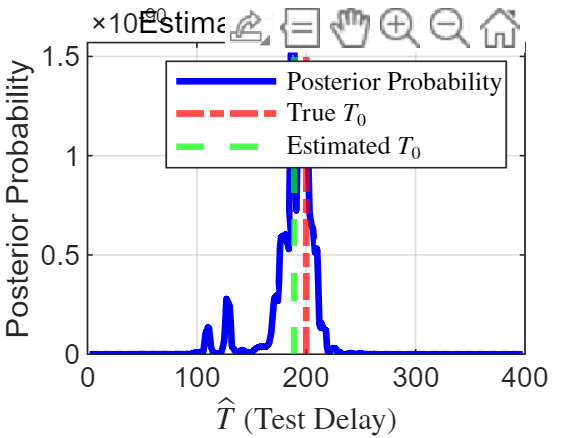


%% 绘制第一次实验的后验概率图
figure;
plot(2:N-2, posterior_prob_all(1, 2:N-2), 'b', 'LineWidth', 2); hold on;
xline(T0, '-.r', 'LineWidth', 2);
xline(estimated_T_hat(1), '--g', 'LineWidth', 2);
title('Estimated Change Point');
xlabel('$\hat{T}$ (Test Delay)', 'Interpreter', 'latex');
ylabel('Posterior Probability');
legend('Posterior Probability', 'True $T_0$', 'Estimated $T_0$', 'Interpreter', 'latex');
grid on;

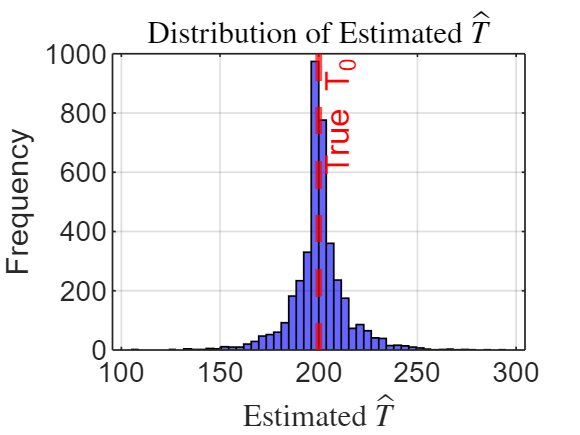


%% 绘制 MSE 分布
figure;
histogram(estimated_T_hat, 50, 'FaceColor', 'blue', 'EdgeColor', 'black');
hold on;
xline(T0, '--r', 'LineWidth', 2, 'Label', 'True T_0');
title('Distribution of Estimated $\hat{T}$', 'Interpreter', 'latex');
xlabel('Estimated $\hat{T}$', 'Interpreter', 'latex');
ylabel('Frequency');
grid on;